% Parameterize the arm
rho = 0.0254; % M, Radius
 
%% Construct pose matrices
% Transformations from world frame to each muscle

% Orientation of muscles in world frame:
pitch_angle = pi/4;
orntn_muscles = eul2rotm([0, -pitch_angle, 0], 'xyz');

% Posese of muscle in world frame
% Muscles are arranged in equilateral triangle with radius rho
g_o = SE3(eul2rotm([0, -pi/2, 0], 'xyz'), [0 0 0.5]);
g_A = SE3(eul2rotm([0, 0, 4*pi/3], 'xyz') * orntn_muscles, [sqrt(3)/2, -1/2, 0] * rho);
g_B = SE3(eul2rotm([0, 0, 2*pi/3], 'xyz') * orntn_muscles, [-sqrt(3)/2, -1/2, 0] * rho);
g_C = SE3(orntn_muscles, [0, 1, 0] * rho);

l_0 = 0.4; % Default length

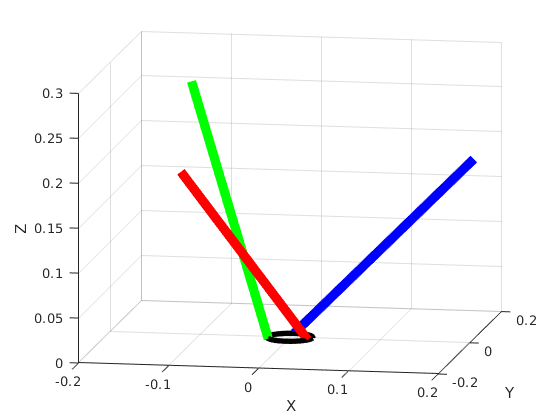

helical_arm_obj = HelicalArm(g_o, {g_A, g_B, g_C}, l_0);
helical_arm_obj.rho = rho;

fig2 = figure();
ax = axes(fig2);
helical_arm_obj.initialize_plotting(ax, ...
    "line_options_circles", line_options_rings, ...
    "line_options_muscles", line_options_muscles, ...
    "resolution", 40);

border_length_cm = 20;
xlim(ax, [-1, 1] * border_length_cm/100);
ylim(ax, [-1, 1] * border_length_cm/100);

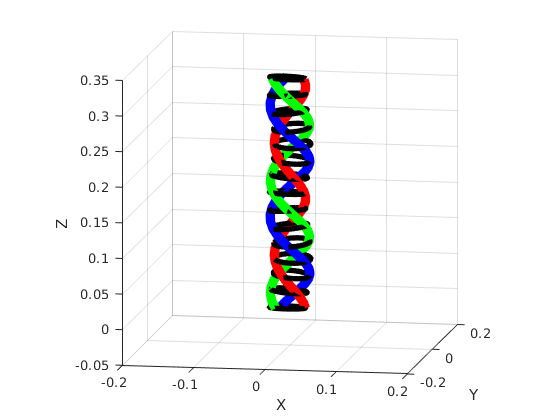

l_A = 0.415; % Red
l_B = 0.48; % Green
l_C = 0.485;  % Blue

v_l = [l_A; l_B; l_C];
helical_arm_obj.update_arm(v_l);